# Presentación Final (Cinemática Diferencial de Piernas)

## Daniel Castillo López A01737357

- **Obtener **la matriz de  transformación **homogénea global T, empleando variables simbólicas** de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base). Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final.

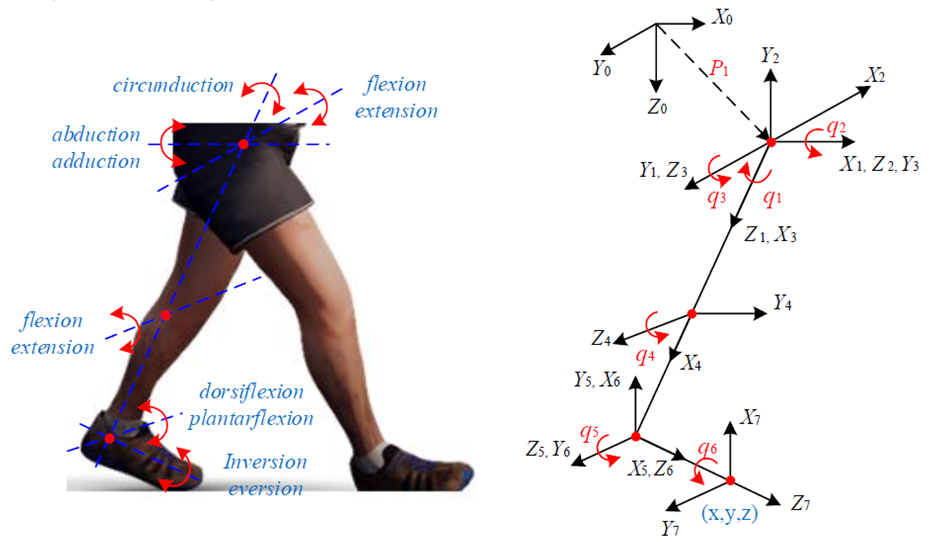

- **Desarrollar** el modelo de **cinemática diferencial simbólica** para cada uno de los sistemas descritos anteriormente y obtener los vectores de la **velocidad angular y velocidad lineal** aplicando variables simbólicas para su análisis en cada caso.

- **Implementar** el código requerido para generar el cálculo de las matrices **homogéneas simbólicas (H1, H2, H3, etc.),** la matriz de **transformación simbólica (T)** y los vectores de **velocidades simbólicas (v, w)** de cada sistema.


clear; clc; close all

En esta sección se definen las variables simbólicas que representan los parámetros articulares del robot: tres ángulos rotacionales y un desplazamiento prismatico, junto con sus respectivas velocidades. Estas variables son necesarias para construir las expresiones simbólicas de la cinemática directa y diferencial.

%% Definición simbólica de variables y velocidades articulares
syms theta1 theta2 theta3 d4 real           % Ángulos articulares (rad) y desplazamiento prismatico
syms dtheta1 dtheta2 dtheta3 dd4 real       % Velocidades articulares
dq = [dtheta1; dtheta2; dtheta3; dd4];      % Vector de velocidades articulares

Aquí se construyen las matrices homogéneas utilizando la clase SE3, que combina rotación y traslación en el espacio tridimensional. Cada matriz representa una transformación entre eslabones consecutivos del robot, permitiendo describir la posición y orientación relativas en función de las variables articulares.

%% Matrices homogéneas simbólicas para cada eslabón
% Cada matriz SE3 combina rotación y traslación simbólica

H0 = SE3();                                % Base (identidad)
H1 = SE3(roty(theta1), [0 0 0]);           % Rotación alrededor de Y: theta1
H2 = SE3(rotx(pi/2), [0 0 0]) * SE3(roty(theta2), [0 0 0]); % Rotación compuesta: 90° sobre X + theta2 sobre Y
H3 = SE3(rotx(pi/2), [0 0 0]) * SE3(roty(theta3), [0 0 0]); % Similar para theta3
H4 = SE3(rotx(0), [3 0 0]);                 % Traslación fija de 3 unidades en X
H5 = SE3(rotz(pi/2), [3 0 0]);              % Rotación 90° en Z y traslación 3 en X
H6 = SE3(rotx(pi/2), [0 0 0]) * SE3(roty(pi/2), [0 0 0]); % Rotación compuesta fija
H7 = SE3(rotx(0), [0 0 d4]);                % Movimiento prismatico d4 en Z

Esta parte realiza la multiplicación secuencial de las matrices homogéneas para obtener la matriz de transformación global desde la base hasta el efector final. El resultado es la matriz t07, que representa la pose (posición y orientación) total del extremo del robot respecto a la base.

%% Cadena cinemática simbólica global
% Multiplicación secuencial para obtener la matriz de transformación total

T01 = H0 * H1;
T02 = T01 * H2;
T03 = T02 * H3;
T04 = T03 * H4;
T05 = T04 * H5;
T06 = T05 * H6;
T07 = T06 * H7;        % Matriz homogénea total hasta el efector final

Una vez obtenida la matriz de transformación total, se extrae el vector de posición tridimensional del efector final tomando los tres primeros elementos de la última columna de la matriz t. Este vector contiene las coordenadas simbólicas en el espacio cartesiano.

%% Extracción de la posición del efector final
T = T07.T;               % Extraemos la matriz 4x4
p = T(1:3, 4);           % Vector posición (x, y, z) simbólico del efector final

En esta sección se construye el Jacobiano lineal a partir de la derivada del vector de posición respecto a las variables articulares. Esta matriz relaciona directamente las velocidades articulares con las velocidades lineales del efector final.

%% Cálculo del Jacobiano lineal
q = [theta1; theta2; theta3; d4];            % Variables articulares
Jv = simplify(jacobian(p, q));               % Jacobiano lineal: derivadas parciales de posición respecto a q

Se calcula el Jacobiano angular construyendo los vectores del eje Z de cada articulación en coordenadas globales. Estos vectores representan los ejes de rotación de cada articulación y permiten determinar cómo las rotaciones articulares afectan la velocidad angular del efector final.

%% Cálculo del Jacobiano angular
% Definición de los vectores z de cada articulación para el cálculo angular
Z0 = [0; 0; 1];                              % Eje Z base

R01 = T01.T;
Z1 = R01(1:3, 1:3) * [0; 0; 1];              % Eje Z del primer eslabón en coordenadas globales

R02 = T02.T;
Z2 = R02(1:3, 1:3) * [0; 0; 1];              % Segundo eslabón

R03 = T03.T;
Z3 = R03(1:3, 1:3) * [0; 0; 1];              % Tercer eslabón

Jw = [Z0, Z1, Z2, [0; 0; 0]];                 % Jacobiano angular (prismatico no aporta rotación)

Se aplican los Jacobianos lineal y angular a las velocidades articulares para obtener expresiones simbólicas de la velocidad lineal (V) y velocidad angular (W) del efector final. Estas expresiones se simplifican para una representación más compacta y clara.

%% Cálculo de velocidades simbólicas del efector final
v = simplify(Jv * dq);                        % Velocidad lineal
w = simplify(Jw * dq);                        % Velocidad angular

%% Mostrar resultados en consola
disp('=== Matriz homogénea simbólica T07 ===');disp(simplify(T))

=== Matriz homogénea simbólica T07 ===


$$\left(\begin{array}{cccc} -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 6\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+d_{4}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+6\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{2}\right) & 6\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-d_{4}\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 6\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-d_{4}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-6\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


disp('=== Jacobiano lineal Jv ===');disp(simplify(Jv))

=== Jacobiano lineal Jv ===


$$\begin{array}{l} \left(\begin{array}{cccc} 6\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-d_{4}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-6\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\sigma_{1} & 6\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-6\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ 0 & 6\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)+d_{4}\,\sin\left(\theta_{2}\right) & -6\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{2}\right)\\ -6\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-d_{4}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-6\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1} & 6\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)+6\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=6\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-d_{4}\,\cos\left(\theta_{2}\right) \end{array}$$


disp('=== Jacobiano angular Jw ===');disp(simplify(Jw))

=== Jacobiano angular Jw ===


$$\left(\begin{array}{cccc} 0 & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 0\\ 0 & 0 & -\cos\left(\theta_{2}\right) & 0\\ 1 & \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 0 \end{array}\right)$$


disp('=== Velocidad lineal simbólica v ===');disp(v)

=== Velocidad lineal simbólica v ===


$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{dtheta}}_{3}\,\left(6\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-6\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right)-{\mathrm{dtheta}}_{1}\,\left(d_{4}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-6\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+6\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\right)+{\mathrm{dd}}_{4}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-{\mathrm{dtheta}}_{2}\,\cos\left(\theta_{1}\right)\,\sigma_{1}\\ {\mathrm{dtheta}}_{2}\,\left(6\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)+d_{4}\,\sin\left(\theta_{2}\right)\right)-{\mathrm{dd}}_{4}\,\cos\left(\theta_{2}\right)-6\,{\mathrm{dtheta}}_{3}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ {\mathrm{dtheta}}_{3}\,\left(6\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)+6\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\right)-{\mathrm{dtheta}}_{1}\,\left(6\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+d_{4}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+6\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\right)-{\mathrm{dd}}_{4}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+{\mathrm{dtheta}}_{2}\,\sin\left(\theta_{1}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=6\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)-d_{4}\,\cos\left(\theta_{2}\right) \end{array}$$


disp('=== Velocidad angular simbólica w ===');disp(w)

=== Velocidad angular simbólica w ===


$$\left(\begin{array}{c} {\mathrm{dtheta}}_{2}\,\sin\left(\theta_{1}\right)+{\mathrm{dtheta}}_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -{\mathrm{dtheta}}_{3}\,\cos\left(\theta_{2}\right)\\ {\mathrm{dtheta}}_{1}+{\mathrm{dtheta}}_{2}\,\cos\left(\theta_{1}\right)-{\mathrm{dtheta}}_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}\right)$$

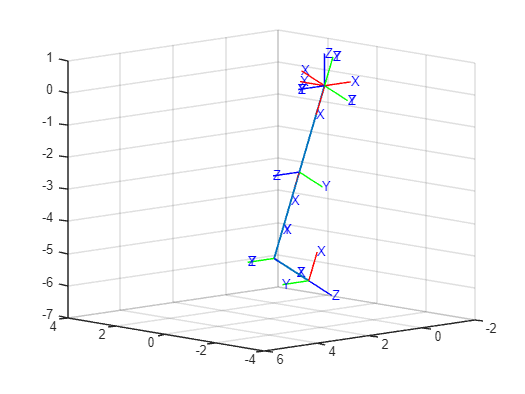


%% Animación numérica con valores específicos para las variables articulares

% Definir valores numéricos de las articulaciones (rad y metros)
theta1_v = -20*pi/180;
theta2_v = -pi/2;
theta3_v = -pi/2;
d4_v = 1.5;

% Definimos las matrices homogéneas numéricas con los valores asignados
H0 = SE3();
H1 = SE3(roty(theta1_v), [0 0 0]);
H2 = SE3(rotx(pi/2), [0 0 0]) * SE3(roty(theta2_v), [0 0 0]);
H3 = SE3(rotx(pi/2), [0 0 0]) * SE3(roty(theta3_v), [0 0 0]);
H4 = SE3(rotx(0), [3 0 0]);
H5 = SE3(rotz(pi/2), [3 0 0]);
H6 = SE3(rotx(pi/2), [0 0 0]) * SE3(roty(pi/2), [0 0 0]);
H7 = SE3(rotx(0), [0 0 d4_v]);

% Cadena cinemática numérica acumulada
H0_1 = H0 * H1;
H1_2 = H0_1 * H2;
H2_3 = H1_2 * H3;
H3_4 = H2_3 * H4;
H4_5 = H3_4 * H5;
H5_6 = H4_5 * H6;
H6_7 = H5_6 * H7;

% Obtener posiciones para graficar la trayectoria del efector final
P = [transl(H0);
     transl(H0_1);
     transl(H1_2);
     transl(H2_3);
     transl(H3_4);
     transl(H4_5);
     transl(H5_6);
     transl(H6_7)];
x = P(:,1); y = P(:,2); z = P(:,3);

%% Graficar trayectoria y animar los marcos
figure
plot3(x, y, z, 'LineWidth', 1.5);            % Trayectoria del efector final
axis([-4 4 -2 6 -7 1]);
grid on;
view(-133, 10);
hold on;

% Graficar marco base
trplot(H0, 'rgb', 'axis', [-4 4 -2 6 -7 1])
snapnow   % << Captura la imagen en el Live Script

% Animar cada transformación entre marcos consecutivos
tranimate(H0, H0_1, 'rgb', 'axis', [-4 4 -2 6 -7 1])
snapnow

tranimate(H0_1, H1_2, 'rgb', 'axis', [-4 4 -2 6 -7 1])
snapnow

tranimate(H1_2, H2_3, 'rgb', 'axis', [-4 4 -2 6 -7 1])
snapnow

tranimate(H2_3, H3_4, 'rgb', 'axis', [-4 4 -2 6 -7 1])
snapnow

tranimate(H3_4, H4_5, 'rgb', 'axis', [-4 4 -2 6 -7 1])
snapnow

tranimate(H4_5, H5_6, 'rgb', 'axis', [-4 4 -2 6 -7 1])
snapnow

tranimate(H5_6, H6_7, 'rgb', 'axis', [-4 4 -2 6 -7 1])

snapnow
